# Inference of Model

## Load and import dataset

clear all; load('data/Density_inference.mat','data'); load('coastlines.mat'); addpath('functions/')
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

Histogram relatively close to normal distribution -> no transofmration used

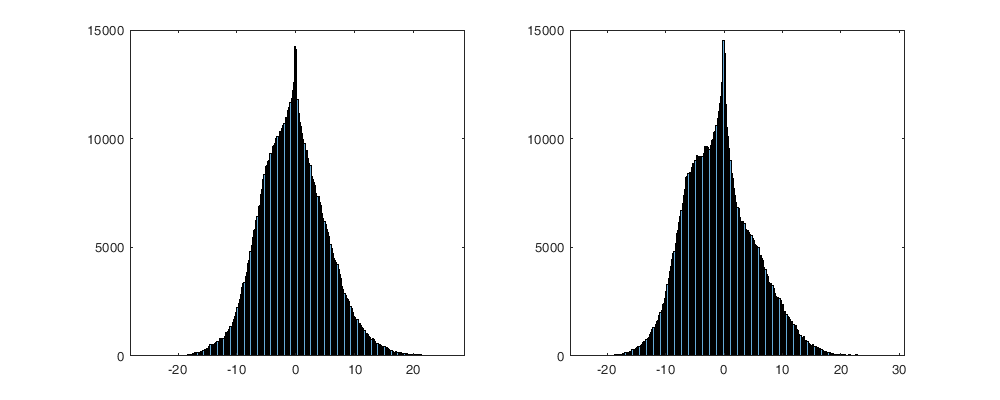

figure('position',[0 0 1000 400]);
subplot(1,2,1); histogram(data.us);
subplot(1,2,2); histogram(data.vs);

No clear non-stionarinarity with NNT -> no trend used

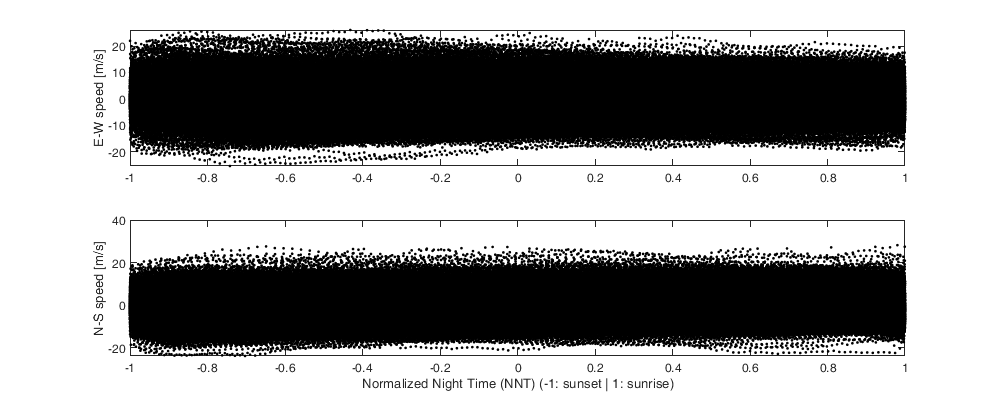

figure('position',[0 0 1000 400]);  
subplot(2,1,1);plot(data.NNT,data.us,'.k'); ylabel('E-W speed [m/s]');
subplot(2,1,2);plot(data.NNT,data.vs,'.k');ylabel('N-S speed [m/s]');
xlabel('Normalized Night Time (NNT) (-1: sunset | 1: sunrise)'); 

Average Daily

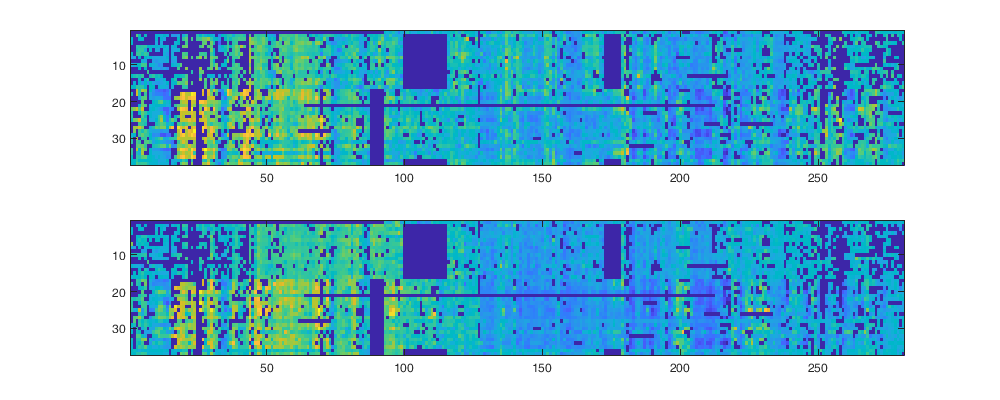

fmulti.t = data.day;
fmulti.r = 1:data.nrad;
[fmulti.R,fmulti.T]=meshgrid(fmulti.r,fmulti.t);

G = findgroups(data.day_id);
fmulti.Mus = splitapply(@nanmean,data.us,G);
fmulti.Mvs = splitapply(@nanmean,data.vs,G);
fmulti.isnan = isnan(fmulti.Mus);

figure('position',[0 0 1000 400]); hold on;
subplot(2,1,1); imagesc(fmulti.Mus')
subplot(2,1,2); imagesc(fmulti.Mvs')

Block décomposition

fmulti.b = nan(size(fmulti.t));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        fmulti.b(fmulti.t>=data.block.date(i_b) | fmulti.t<data.block.date(1)) = i_b;
    else
        fmulti.b(fmulti.t>=data.block.date(i_b) & fmulti.t<data.block.date(i_b+1)) = i_b;
    end
end
fmulti.B = repmat(fmulti.b,1,data.nrad);
data.day_b = fmulti.b;

fmulti_poly_t_degree=0;
fmulti_poly_d_degree=1;

X = trend(fmulti.T,data.lat(fmulti.R),data.lon(fmulti.R),fmulti_poly_t_degree,fmulti_poly_d_degree);

fmulti.f_trend = @(t,lat,lon,beta) reshape(trend(t(:),lat(:),lon(:),fmulti_poly_t_degree,fmulti_poly_d_degree) * beta(:), size(t));

fmulti.Mus_n = nan(size(fmulti.Mus)); fmulti.Mvs_n = fmulti.Mus_n;
fmulti.beta_u = nan(fmulti_poly_t_degree + fmulti_poly_d_degree*2 +1 ,numel(data.block.date));
fmulti.beta_v = fmulti.beta_u;

We loop over all block...

for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    fmulti.beta_u(:,i_b) = ( X(id,:)' * X(id,:) ) \ (X(id,:)' * fmulti.Mus(id) );
    fmulti.beta_v(:,i_b) = ( X(id,:)' * X(id,:) ) \ (X(id,:)' * fmulti.Mvs(id) );
    fmulti.Mus_n(id) = fmulti.Mus(id)-fmulti.f_trend(fmulti.T(id),data.lat(fmulti.R(id)),data.lon(fmulti.R(id)),fmulti.beta_u(:,i_b));
    fmulti.Mvs_n(id) = fmulti.Mvs(id)-fmulti.f_trend(fmulti.T(id),data.lat(fmulti.R(id)),data.lon(fmulti.R(id)),fmulti.beta_v(:,i_b));
end

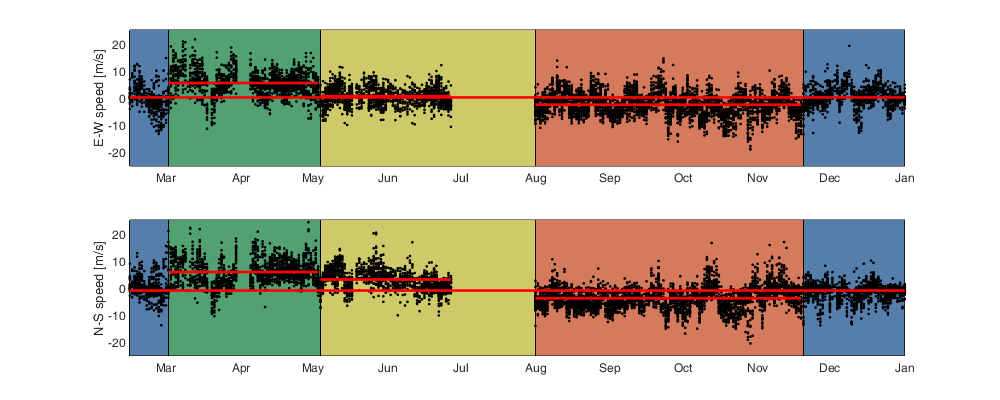

figure('position',[0 0 1000 400]);
subplot(2,1,1); hold on
for i_b=1:numel(data.block.date)-1
    fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[25 -25 -25 25],data.block.col(i_b,:))
end
fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[25 -25 -25 25],data.block.col(4,:))
fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[25 -25 -25 25],data.block.col(4,:))
plot(fmulti.T(:),fmulti.Mus(:),'.k'); 
for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    t_tmp = sort(unique(fmulti.T(id)));
    plot(t_tmp, fmulti.f_trend(t_tmp,mean(data.lat(fmulti.R(id)))*ones(numel(t_tmp),1),mean(data.lon(fmulti.R(id)))*ones(numel(t_tmp),1), fmulti.beta_u(:,i_b)),'-r','Linewidth',2)
end
ylabel('E-W speed [m/s]'); datetick('x'); axis tight;

subplot(2,1,2); hold on
for i_b=1:numel(data.block.date)-1
    fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[25 -25 -25 25],data.block.col(i_b,:))
end
fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[25 -25 -25 25],data.block.col(4,:))
fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[25 -25 -25 25],data.block.col(4,:))
plot(fmulti.T(:),fmulti.Mvs(:),'.k'); 
for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    t_tmp = sort(unique(fmulti.T(id)));
    plot(t_tmp, fmulti.f_trend(t_tmp,mean(data.lat(fmulti.R(id)))*ones(numel(t_tmp),1),mean(data.lon(fmulti.R(id)))*ones(numel(t_tmp),1), fmulti.beta_v(:,i_b)),'-r','Linewidth',2)
end
ylabel('N-S speed [m/s]'); datetick('x'); axis tight;

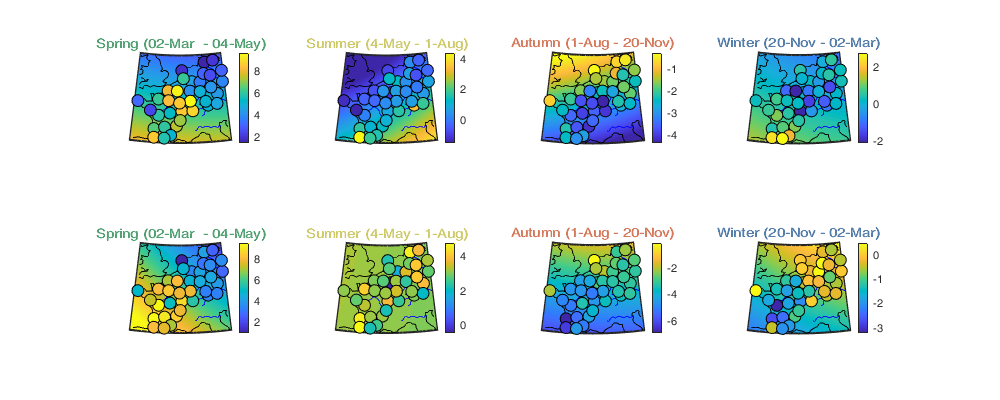

figure('position',[0 0 1000 400]); hold on; 
[LAT, LON] = meshgrid(floor(min(data.lat)):.1:ceil(max(data.lat)),floor(min(data.lon)):.1:ceil(max(data.lon)));
for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    subplot(2,4,i_b,'Color',data.block.col(i_b,:)); hold on; h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    surfm(LAT,LON,fmulti.f_trend(mean(fmulti.T(id))*ones(size(LAT)),LAT,LON,fmulti.beta_u(:,i_b))) 
    plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
    [G,tmp]=findgroups(fmulti.R(id));
    tmp2 = splitapply(@mean,fmulti.Mus(id),G);
    scatterm(data.lat(tmp),data.lon(tmp),80,tmp2,'filled','MarkerEdgeColor','k'); 
    title(data.block.date_str{i_b},'Color',data.block.col(i_b,:) ); caxis([min(tmp2) max(tmp2)]); colorbar
    
    subplot(2,4,4+i_b,'Color',data.block.col(i_b,:)); hold on; h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    surfm(LAT,LON,fmulti.f_trend(mean(fmulti.T(id))*ones(size(LAT)),LAT,LON,fmulti.beta_v(:,i_b))) 
    plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
    tmp2 = splitapply(@mean,fmulti.Mvs(id),G);
    scatterm(data.lat(tmp),data.lon(tmp),80,tmp2,'filled','MarkerEdgeColor','k'); 
    title(data.block.date_str{i_b},'Color',data.block.col(i_b,:) ); caxis([min(tmp2) max(tmp2)]); colorbar
end

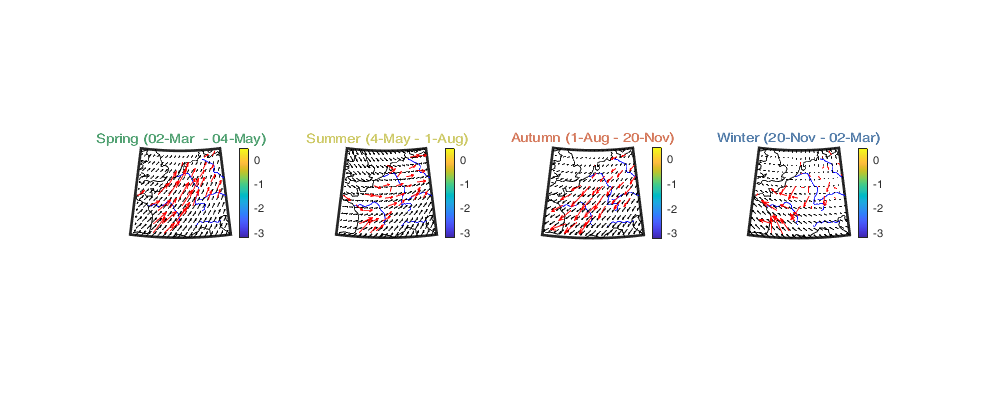

figure('position',[0 0 1000 400]);hold on; 
[LAT, LON] = meshgrid(floor(min(data.lat)):1:ceil(max(data.lat)),floor(min(data.lon)):1:ceil(max(data.lon)));
for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    subplot(1,4,i_b,'Color',data.block.col(i_b,:)); hold on; h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
    [G,tmp]=findgroups(fmulti.R(id));
    tmpu = splitapply(@mean,fmulti.Mus(id),G);
    tmpv = splitapply(@mean,fmulti.Mvs(id),G);
    quiverm(LAT,LON,fmulti.f_trend(mean(fmulti.T(id))*ones(size(LAT)),LAT,LON,fmulti.beta_u(:,i_b)),fmulti.f_trend(mean(fmulti.T(id))*ones(size(LAT)),LAT,LON,fmulti.beta_v(:,i_b)),'k'); 
    quiverm(data.lat(tmp),data.lon(tmp),tmpu,tmpv,'r'); 
    title(data.block.date_str{i_b},'Color',data.block.col(i_b,:) ); caxis([min(tmp2) max(tmp2)]); colorbar
end

clear LAT LON T t_tmp tmp* G X id i_b h 

## Covariance Multi

cov.d=[0 1 150 200 300 400 500 750 1000 2000];
cov.t=[0 1 2 3 4 5 10 20];
[cov.D,cov.T] = meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1));

cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)-1);
cov.T_emp = cov.D_emp;
cov.emp_grid_u = nan(size(cov.D));
cov.emp_grid_v = cov.emp_grid_u;

cov.nb=nan(numel(data.block.date)-1,1);
for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    cov.nb(i_b)=sum(id(:));
    Dtime=squareform(pdist(fmulti.T(id)));
    Ddist=squareform(pdist([data.lat(fmulti.R(id)) data.lon(fmulti.R(id))],@lldistkm));
    
    cov_emp_u = bsxfun(@times, fmulti.Mus_n(id)', fmulti.Mus_n(id));
    cov_emp_v = bsxfun(@times, fmulti.Mvs_n(id)', fmulti.Mvs_n(id));
    
    for i_t=1:numel(cov.t)-1
        for i_d=1:numel(cov.d)-1
            id = Dtime>=cov.t(i_t) & Dtime<cov.t(i_t+1) & Ddist>=cov.d(i_d) & Ddist<cov.d(i_d+1);
            cov.D_emp(i_t,i_d,i_b) = nanmean(Ddist(id));
            cov.T_emp(i_t,i_d,i_b) = nanmean(Dtime(id));
            cov.emp_grid_u(i_t,i_d,i_b) = nanmean( cov_emp_u(id) );
            cov.emp_grid_v(i_t,i_d,i_b) = nanmean( cov_emp_v(id) );
        end
    end
end

Figure

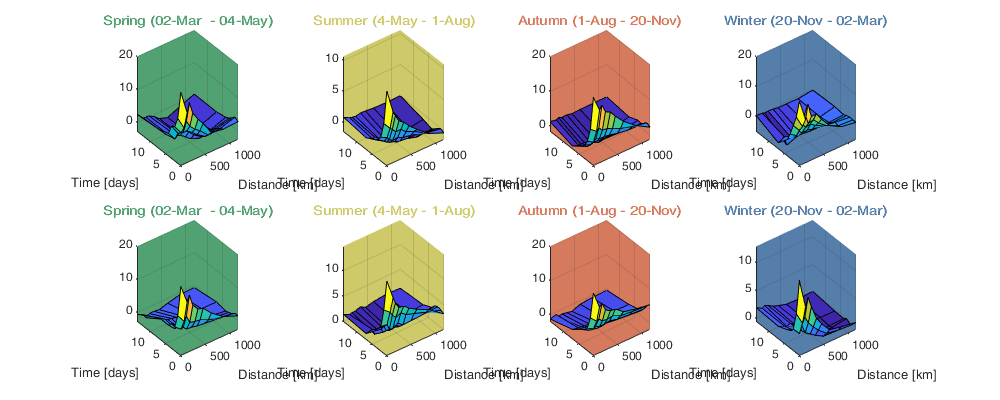

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_u(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); 
    
    subplot(2,4,4+i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); 
end

## Covariance function fit

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(3),parm(4),parm(5),parm(6),parm(7));

parm0 =[8 10 500 5 .5 .5 .5 ]';


for i_b=1:numel(data.block.date)
    id = find(~fmulti.isnan & fmulti.B==i_b);
    
    nugget_max = abs(diff(maxk(reshape(cov.emp_grid_u(:,:,i_b),1,[]),2)));
    parm_min=[0.8*nugget_max 1 100 1 .8 .8 0]';
    parm_max=[1.2*nugget_max nancov(fmulti.Mus_n(id)) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( ( 1000*max(cov.emp_grid_u(:,:,i_b),0.1).*(Gneiting_fit(parm,i_b) - cov.emp_grid_u(:,:,i_b)) ).^2 )); % 1000*max(cov.emp_grid(:,:,i_b),0).*
    fmulti.cov.parm_u(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 0 0 0 0 0],nancov(fmulti.Mus_n(id)),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
    
    nugget_max = abs(diff(maxk(reshape(cov.emp_grid_v(:,:,i_b),1,[]),2)));
    parm_min=[0.9*nugget_max 1 100 1 .8 .8 0 ]';
    parm_max=[1.2*nugget_max nancov(fmulti.Mvs_n(id)) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( ( 1000*max(cov.emp_grid_v(:,:,i_b),0.1).*(Gneiting_fit(parm,i_b) - cov.emp_grid_v(:,:,i_b)) ).^2 )); % 1000*max(cov.emp_grid(:,:,i_b),0.1).*
    fmulti.cov.parm_v(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 0 0 0 0 0],nancov(fmulti.Mvs_n(id)),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
end

fmulti.cov.C_un = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2).*Gneiting(D,T,parm(3),parm(4),parm(5),parm(6),parm(7));
fmulti.cov.C_vn = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2).*Gneiting(D,T,parm(3),parm(4),parm(5),parm(6),parm(7));
fmulti.cov.C_u  = @(D,T,parm) parm(2).*Gneiting(D,T,parm(3),parm(4),parm(5),parm(6),parm(7));
fmulti.cov.C_v  = @(D,T,parm) parm(2).*Gneiting(D,T,parm(3),parm(4),parm(5),parm(6),parm(7));

Ilustration of the fitted covariance function

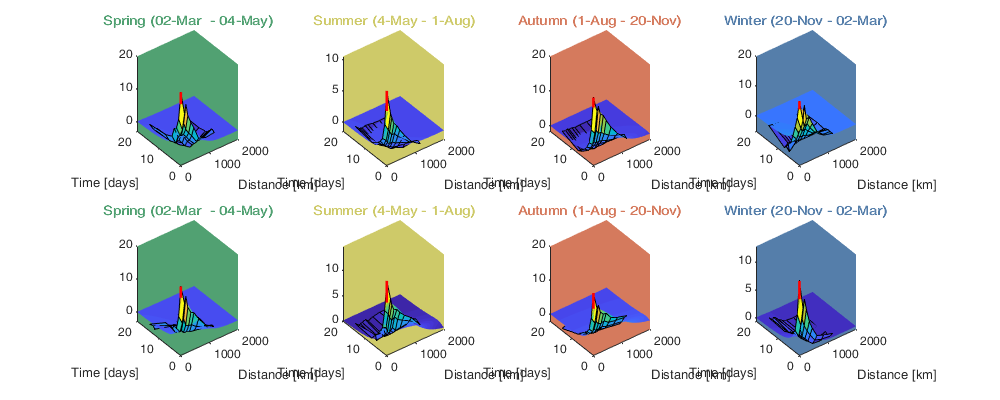

[tmpD,tmpT] = meshgrid(cov.d(1):1:cov.d(end),cov.t(1):0.1:cov.t(end));

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); hold on
    s=surf(tmpD,tmpT,fmulti.cov.C_un(tmpD, tmpT,fmulti.cov.parm_u(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_u(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    plot3([0 0],[0 0],[fmulti.cov.parm_u(2,i_b) sum(fmulti.cov.parm_u(1:2,i_b))],'r', 'linewidth',2)
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); view(3)
    
    subplot(2,4,4+i_b);  hold on
    s=surf(tmpD,tmpT,fmulti.cov.C_vn(tmpD, tmpT,fmulti.cov.parm_v(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 

    plot3([0 0],[0 0],[fmulti.cov.parm_v(2,i_b) sum(fmulti.cov.parm_v(1:2,i_b))],'r', 'linewidth',2)
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); view(3)
end

Clear all un-necessary variable

%clear C cov* Ddist Dtime Gneiting_fit h i* L* parm* rmse s tmp*

## Intra-night scale

At the intra-night scale, we model the the fluctuation around the multi-night scale

fintra.Ius = data.us-fmulti.Mus(data.day_id,:);
fintra.Ivs = data.vs-fmulti.Mvs(data.day_id,:);
fintra_isnan = isnan(fintra.Ius);

Block decomposition

fintra_b = nan(size(data.time));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        fintra_b(datenum(data.time)>=data.block.date(4) | datenum(data.time)<data.block.date(1)) = i_b;
    else
        fintra_b(datenum(data.time)>=data.block.date(i_b) & datenum(data.time)<data.block.date(i_b+1)) = i_b;
    end
end
fintra_B = repmat(fintra_b,1,data.nrad);

In addition to present a trend of the mean, the intra-night components also contains a non-stationarity of variance along the night (see figure below). We fit another polynomial function to normalize the variance


$$\sigma_I \left(t,\mathit{\mathbf{s}}\right)=\sum_{i=i}^{10} b_i \textrm{NNT}\left(t,\mathit{\mathbf{s}}\right)$$


fintra_poly_degree=4;
X=bsxfun(@power,data.NNT(:),fintra_poly_degree:-1:0);
fintra.f_trend = @(t,beta_v) reshape(bsxfun(@power,t(:),fintra_poly_degree:-1:0) * beta_v(:),size(t));

We will then compute the detrended value of the multi-night scale componenent

fintra_Ius_var = nan(size(fintra.Ius));
fintra_Ivs_var = fintra_Ius_var;
fintra_beta_u = nan(fintra_poly_degree+1,numel(data.block.date));
fintra_beta_v = nan(fintra_poly_degree+1,numel(data.block.date));

We loop over all block...

for i_b=1:numel(data.block.date)
    id = fintra_B==i_b & ~fintra_isnan;
    fintra_beta_u(:,i_b) = (X(id,:)'*X(id,:))\(X(id,:)'*fintra.Ius(id).^2);
    fintra_beta_v(:,i_b) = (X(id,:)'*X(id,:))\(X(id,:)'*fintra.Ivs(id).^2);
    fintra_Ius_var(id) = fintra.f_trend(data.NNT(id),fintra_beta_u(:,i_b));
    fintra_Ivs_var(id) = fintra.f_trend(data.NNT(id),fintra_beta_v(:,i_b));
end

Illustration

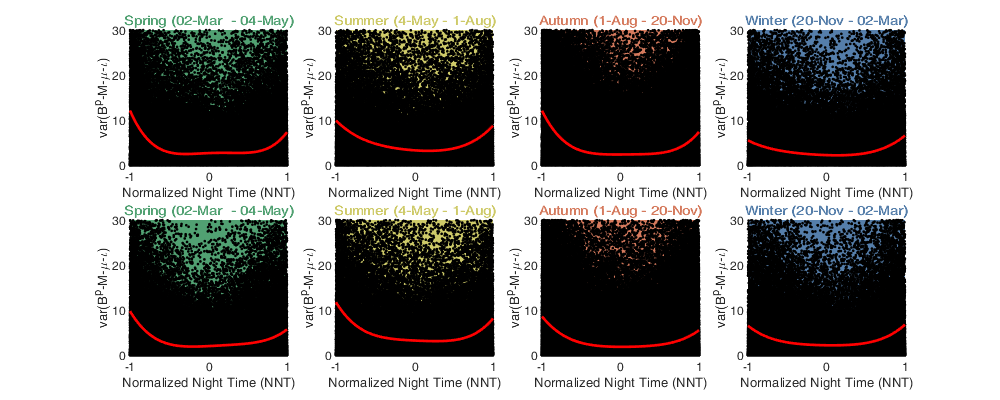

NNT_axis=-1:.01:1;
figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    id = fintra_B==i_b & ~fintra_isnan;
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),fintra.Ius(id).^2,'.k');
    plot(NNT_axis, fintra.f_trend(NNT_axis,fintra_beta_u(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 30]); xlim([-1 1])
    
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); hold on
    plot(data.NNT(id),fintra.Ivs(id).^2,'.k');
    plot(NNT_axis, fintra.f_trend(NNT_axis,fintra_beta_v(:,i_b)),'-r','linewidth',2);
    title(data.block.date_str{i_b},'color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); 
    xlabel('Normalized Night Time (NNT)'); ylabel('var(B^p-M-\mu-\iota)');ylim([0 30]); xlim([-1 1])
end

Finally, combining the polynomial of the curve and the correction for variance, we find the de-trended intra-night scale $I$

fintra.Ius_n = fintra.Ius(~fintra_isnan) ./ sqrt(fintra_Ius_var(~fintra_isnan));
fintra.Ivs_n = fintra.Ivs(~fintra_isnan) ./ sqrt(fintra_Ivs_var(~fintra_isnan));

clear X fintra_* NNT_axis i*

## 4.2 Covariance function of $I\left(t,\mathit{\mathbf{s}}\right)$

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([data.lat data.lon], @lldistkm));
tmp=repmat(1:data.nrad,data.ntime,1);
fintra_radar = uint8(tmp(~fintra_isnan));
tmp=repmat(data.day(data.day_id),1,data.nrad);
fintra_day = single(tmp(~fintra_isnan));
tmp=repmat(datenum(data.time),1,data.nrad);
fintra_time = tmp(~fintra_isnan);

cov.d=[0 1 100 150 200 250 300 600 1000];
cov.t=[0 .01 .02 .05 .07 .1 .2];
[cov.D,cov.T]=meshgrid(cov.d(1:end-1)+diff(cov.d)/2,cov.t(1:end-1)+diff(cov.t)/2);
cov.D_emp=nan(size(cov.D,1),size(cov.D,2),numel(data.block.date)); 
cov.T_emp=nan(size(cov.D_emp));
cov.emp_grid_u=nan(size(cov.D_emp));
cov.emp_grid_v=nan(size(cov.D_emp));

for i_b=1:numel(data.block.date)

    D = nan(1000000000,2);
    Did = zeros(1000000000,2,'uint32');
    i=0;
    for i_t=data.day(data.day_b==i_b)'
        id = find(fintra_day==i_t);
        tmp1 = [reshape(Ddist_sm(fintra_radar(id),fintra_radar(id)),[],1) reshape(squareform(pdist(fintra_time(id))),[],1)];
        tmp2 = [uint32(repmat(id,numel(id),1)) uint32(repelem(id,numel(id)))];
        
        B = tril(ones(numel(id)));
        id2=B(:)==1 & tmp1(:,1)<cov.d(end) & tmp1(:,2)<cov.t(end);
        D(i+(1:sum(id2)),:)=tmp1(id2,:);
        Did(i+(1:sum(id2)),:)=tmp2(id2,:);
        i=i+sum(id2);
    end
    D=D(1:i,:);
    Did=Did(1:i,:);

    
    for i_d=1:numel(cov.d)-1
        id1 = find(D(:,1)>=cov.d(i_d) & D(:,1)<cov.d(i_d+1));
        for i_t=1:numel(cov.t)-1
            id2 = id1(D(id1,2)>=cov.t(i_t) & D(id1,2)<cov.t(i_t+1));
            cov.emp_grid_u(i_t,i_d,i_b)= mean(fintra.Ius_n(Did(id2,1)) .* fintra.Ius_n(Did(id2,2)));
            cov.emp_grid_v(i_t,i_d,i_b)= mean(fintra.Ivs_n(Did(id2,1)) .* fintra.Ivs_n(Did(id2,2)));
            cov.D_emp(i_t,i_d,i_b) = nanmean(D(id2,1));
            cov.T_emp(i_t,i_d,i_b) = nanmean(D(id2,2));
        end
    end
end

Figure

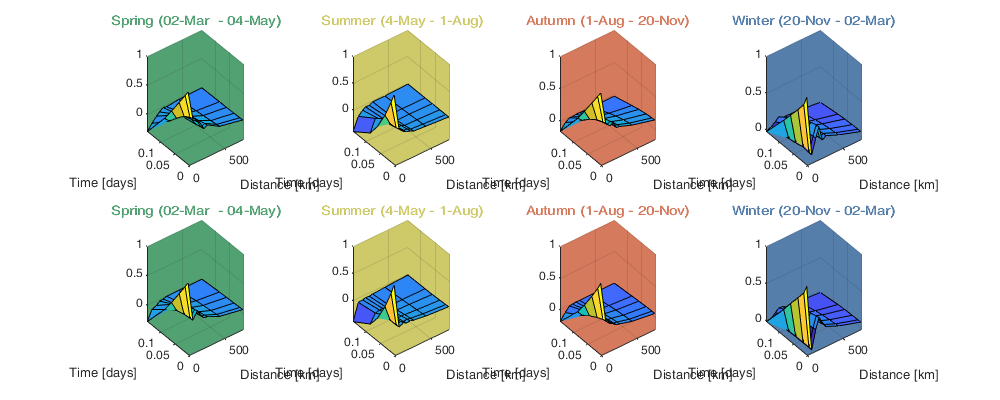

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_u(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); 
    
    subplot(2,4,4+i_b); surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); 
end

Gneiting_fit = @(parm,i_b) parm(1)*(cov.D_emp(:,:,i_b)==0 & cov.T_emp(:,:,i_b)==0) + parm(2)*(cov.D_emp(:,:,i_b)==0) + parm(3).*Gneiting(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),parm(4),parm(5),parm(6),parm(7), parm(8));

parm0 =[0 0.2 1 100 0.1 .5 0 .5]';
parm_min=[0 0.3 0 0.0001 0.1 0 0.8 0]';

for i_b=1:numel(data.block.date)
    parm_max = [cov.emp_grid_u(1,1,i_b) cov.emp_grid_u(1,1,i_b) cov.emp_grid_u(1,1,i_b) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( double(cov.D>0.5) .* 1000.*max(cov.emp_grid_u(:,:,i_b),0).*( (Gneiting_fit(parm,i_b) - cov.emp_grid_u(:,:,i_b)).^2 ) )); % 1000*max(cov.emp_grid(:,:,i_b),0).*
    fintra.cov.parm_u(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 1 0 0 0 0 0],cov.emp_grid_u(1,1,i_b),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
    
    parm_max = [cov.emp_grid_v(1,1,i_b) cov.emp_grid_v(1,1,i_b) cov.emp_grid_u(1,1,i_b) 3000 10 1 1 1 ]';
    rmse = @(parm) nansum(nansum( 1000*max(cov.emp_grid_v(:,:,i_b),0).*( (Gneiting_fit(parm,i_b) - cov.emp_grid_v(:,:,i_b)).^2 ) )); % 
    fintra.cov.parm_v(:,i_b) = fmincon(rmse,parm0,[],[],[1 1 1 0 0 0 0 0],cov.emp_grid_v(1,1,i_b),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));
end

fintra.cov.C_un = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2)*(D==0) + parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));
fintra.cov.C_vn = @(D,T,parm) parm(1)*(D==0 & T==0) + parm(2)*(D==0) + parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));
fintra.cov.C_u  = @(D,T,parm) parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));
fintra.cov.C_v  = @(D,T,parm) parm(3).*Gneiting(D,T,parm(4),parm(5),parm(6),parm(7),parm(8));

Ilustration of the fitted covariance function

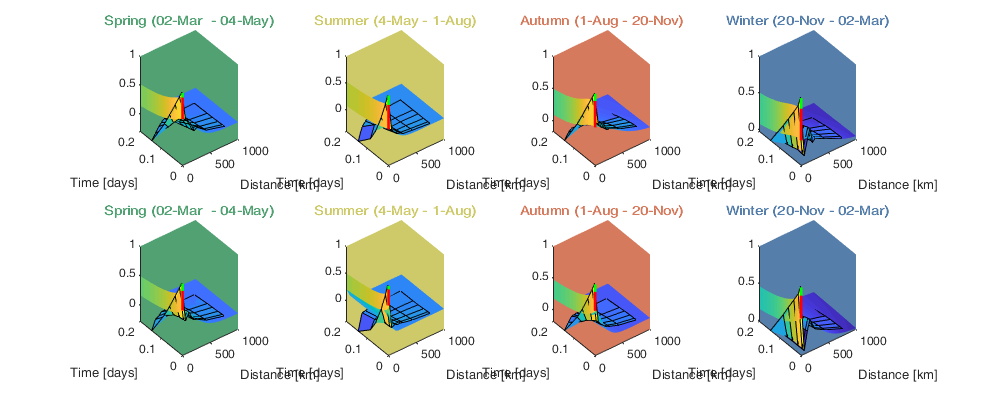

[tmpD,tmpT] = meshgrid(cov.d(1):5:cov.d(end),cov.t(1):0.001:cov.t(end));

figure('position',[0 0 1000 400]);
for i_b = 1:numel(data.block.date)
    subplot(2,4,i_b); hold on
    s=surf(tmpD,tmpT,fintra.cov.C_un(tmpD, tmpT, fintra.cov.parm_u(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_u(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    plot3([0 0],[0 0],[fintra.cov.parm_u(3,i_b) sum(fintra.cov.parm_u(2:3,i_b))],'r', 'linewidth',2)
    plot3([0 0],[0 0],[sum(fintra.cov.parm_u(2:3,i_b)) sum(fintra.cov.parm_u(1:3,i_b))],'g', 'linewidth',2)
    subplot(2,4,i_b,'color',data.block.col(i_b,:)); view(3)
    
    subplot(2,4,4+i_b);  hold on
    s=surf(tmpD,tmpT,fintra.cov.C_vn(tmpD, tmpT, fintra.cov.parm_v(:,i_b))); s.EdgeColor='none';
    surf(cov.D_emp(:,:,i_b),cov.T_emp(:,:,i_b),cov.emp_grid_v(:,:,i_b));
    xlabel('Distance [km]'); ylabel('Time [days]'); title(data.block.date_str{i_b},'Color',data.block.col(i_b,:)); 
    plot3([0 0],[0 0],[fintra.cov.parm_v(3,i_b) sum(fintra.cov.parm_v(2:3,i_b))],'r', 'linewidth',2)

    plot3([0 0],[0 0],[sum(fintra.cov.parm_v(2:3,i_b)) sum(fintra.cov.parm_v(1:3,i_b))],'g', 'linewidth',2)
    subplot(2,4,4+i_b,'color',data.block.col(i_b,:)); view(3)
end

## 5. Save

Save the parameters of the model. 

save('data/Flight_inference.mat','fmulti','fintra','-v7.3')
% load('data/Flight_inference.mat')